
% Notation ud (up, down) is equivalent to opinion S = +1 and sigma = -1, 
% and accordingly uu is S=+1 and sigma = +1, etc.
% The term theta_ud_uu corresponds to θ_{+1,-1}^{+1,+1} as used in the article.

function dydt_uu_uu = fun_e_uu_uu(k, p, alpha, q, c_uu, c_ud, c_du, c_dd, theta_uu_uu, theta_uu_ud, theta_uu_du, theta_uu_dd,...
            theta_ud_uu, theta_ud_ud, theta_ud_du, theta_ud_dd,...
            theta_du_uu, theta_du_ud, theta_du_du, theta_du_dd,...
            theta_dd_uu, theta_dd_ud, theta_dd_du, theta_dd_dd)
    c1 = -c_uu*p*alpha*theta_uu_uu -2*c_uu/k*(1-p)*alpha*theta_uu_uu*(theta_uu_du + theta_uu_dd)^q*(k-q)- 2*c_uu/k*(1-p)*(1-alpha)*theta_uu_uu*(theta_uu_du + theta_uu_dd)^q*(k-q);
    c2 = c_ud*theta_ud_uu*p*alpha + 2*c_ud/k*alpha*(1-p)*theta_ud_uu*(theta_ud_uu + theta_ud_ud)^(q-1)*(q + (k-q)*(theta_ud_uu + theta_ud_ud));
    c3 = 2*c_du*(1-alpha)*theta_du_uu - 2*c_du/k*(1-alpha)*(1-p)*theta_du_uu*(theta_du_du + theta_du_dd)^q*(k-q);

    dydt_uu_uu = c1 + c2 + c3;
end

function dydt_uu_ud = fun_e_uu_ud(k, p, alpha, q, c_uu, c_ud, c_du, c_dd, theta_uu_uu, theta_uu_ud, theta_uu_du, theta_uu_dd,...
            theta_ud_uu, theta_ud_ud, theta_ud_du, theta_ud_dd,...
            theta_du_uu, theta_du_ud, theta_du_du, theta_du_dd,...
            theta_dd_uu, theta_dd_ud, theta_dd_du, theta_dd_dd)
    c1 = -c_uu/k*(1-p)*(1-alpha)*theta_uu_ud*(theta_uu_du + theta_uu_dd)^q*(k-q) + c_uu*1/2*p*alpha*(theta_uu_uu - theta_uu_ud)...
         + c_uu/k*alpha*(1-p)*(theta_uu_uu - theta_uu_ud)*(theta_uu_du + theta_uu_dd)^q*(k-q);
    c2 = (-c_ud*(1-alpha)*theta_ud_uu + c_ud/k*(1-alpha)*(1-p)*theta_ud_uu*(theta_ud_uu + theta_ud_ud)^(q-1)*(q + (k-q)*(theta_ud_uu + theta_ud_ud))... 
        + c_ud*1/2*p*alpha*(theta_ud_ud - theta_ud_uu) + c_ud/k*alpha*(1-p)*(theta_ud_ud - theta_ud_uu)*(theta_ud_ud + theta_ud_uu)^(q-1)*(q + (k-q)*(theta_ud_ud + theta_ud_uu)));
    c3 = c_du*(1-alpha)*theta_du_ud - c_du/k*(1-alpha)*(1-p)*theta_du_ud*(theta_du_du + theta_du_dd)^q*(k-q);
    c4 = c_dd/k*(1-p)*(1-alpha)*theta_dd_uu*(theta_dd_uu + theta_dd_ud)^(q-1)*(q + (k-q)*(theta_dd_uu + theta_dd_ud));

    dydt_uu_ud = c1 + c2 + c3 + c4;
end

function dydt_uu_du = fun_e_uu_du(k, p, alpha, q, c_uu, c_ud, c_du, c_dd, theta_uu_uu, theta_uu_ud, theta_uu_du, theta_uu_dd,...
            theta_ud_uu, theta_ud_ud, theta_ud_du, theta_ud_dd,...
            theta_du_uu, theta_du_ud, theta_du_du, theta_du_dd,...
            theta_dd_uu, theta_dd_ud, theta_dd_du, theta_dd_dd)
     c1 = -c_uu*1/2*p*alpha*theta_uu_du - c_uu/k*alpha*(1-p)*theta_uu_du*(theta_uu_du + theta_uu_dd)^(q-1)*(q + (k-q)*(theta_uu_du + theta_uu_dd))...
        + c_uu/k*(1-p)*(1-alpha)*(-theta_uu_du*(theta_uu_du + theta_uu_dd)^(q-1)*(q + (k-q)*(theta_uu_du + theta_uu_dd))...  
                                                             + theta_uu_uu*(theta_uu_du + theta_uu_dd)^q*(k-q));
    c2 = c_ud*1/2*p*alpha*theta_ud_du + c_ud/k*alpha*(1-p)*theta_ud_du*(theta_ud_uu + theta_ud_ud)^q*(k-q);
    c3 = (c_du*(1-alpha)*(-theta_du_uu + theta_du_du) - c_du/k*(1-alpha)*(1-p)*(-theta_du_uu*(theta_du_du + theta_du_dd)^q*(k-q) ...
         + theta_du_du*(theta_du_du + theta_du_dd)^(q-1)*(q + (k-q)*(theta_du_du + theta_du_dd))) - c_du*1/2*p*alpha*theta_du_uu ... 
         - c_du/k*alpha*(1-p)*theta_du_uu*(theta_du_du + theta_du_dd)^q*(k-q));
    c4 = c_dd*1/2*p*alpha*theta_dd_uu + c_dd/k*alpha*(1-p)*theta_dd_uu*(theta_dd_uu+ theta_dd_ud)^(q-1)*(q + (k-q)*(theta_dd_uu+ theta_dd_ud));

    dydt_uu_du = c1 + c2 + c3 + c4;
end

function dydt_uu_dd = fun_e_uu_dd(k, p, alpha, q, c_uu, c_ud, c_du, c_dd, theta_uu_uu, theta_uu_ud, theta_uu_du, theta_uu_dd,...
            theta_ud_uu, theta_ud_ud, theta_ud_du, theta_ud_dd,...
            theta_du_uu, theta_du_ud, theta_du_du, theta_du_dd,...
            theta_dd_uu, theta_dd_ud, theta_dd_du, theta_dd_dd)
    c1 = - c_uu*1/2*p*alpha*theta_uu_dd- c_uu/k*(1-p)*alpha*theta_uu_dd*(theta_uu_du + theta_uu_dd)^(q-1)*(q + (k-q)*(theta_uu_du + theta_uu_dd))...
         - c_uu/k*(1-p)*(1-alpha)*theta_uu_dd*(theta_uu_du + theta_uu_dd)^(q-1)*(q + (k-q)*(theta_uu_du + theta_uu_dd));
    c2 = (c_ud*1/2*p*alpha*theta_ud_dd + c_ud/k*alpha*(1-p)*theta_ud_dd*(theta_ud_uu + theta_ud_ud)^q*(k-q) + c_ud*(1-alpha)*theta_ud_uu ... 
         - c_ud/k*(1-alpha)*(1-p)*theta_ud_uu*(theta_ud_uu + theta_ud_ud)^(q-1)*(q + (k-q)*(theta_ud_uu + theta_ud_ud)));
    c3 = (c_du*(1-alpha)*theta_du_dd - c_du/k*(1-p)*(1-alpha)*theta_du_dd*(theta_du_du + theta_du_dd)^(q-1)*(q + (k-q)*(theta_du_du + theta_du_dd)) ...
          + c_du*1/2*p*alpha*theta_du_uu + c_du/k*alpha*(1-p)*theta_du_uu*(theta_du_du + theta_du_dd)^q*(k-q));
    c4 = -c_dd*1/2*p*alpha*theta_dd_uu- c_dd/k*alpha*(1-p)*theta_dd_uu*(theta_dd_uu + theta_dd_ud)^(q-1)*(q + (k-q)*(theta_dd_uu + theta_dd_ud))...
     - c_dd/k*(1-alpha)*(1-p)*theta_dd_uu*(theta_dd_uu + theta_dd_ud)^(q-1)*(q + (k-q)*(theta_dd_uu + theta_dd_ud));

    dydt_uu_dd = c1 + c2 + c3 + c4;
end

function dydt_ud_ud = fun_e_ud_ud(k, p, alpha, q, c_uu, c_ud, c_du, c_dd, theta_uu_uu, theta_uu_ud, theta_uu_du, theta_uu_dd,...
            theta_ud_uu, theta_ud_ud, theta_ud_du, theta_ud_dd,...
            theta_du_uu, theta_du_ud, theta_du_du, theta_du_dd,...
            theta_dd_uu, theta_dd_ud, theta_dd_du, theta_dd_dd)
    c1 = c_uu*p*alpha*theta_uu_ud + 2*c_uu/k*alpha*(1-p)*theta_uu_ud*(theta_uu_du + theta_uu_dd)^q*(k-q);
    c2 = (-c_ud*p*alpha*theta_ud_ud - 2*c_ud/k*alpha*(1-p)*theta_ud_ud*(theta_ud_uu + theta_ud_ud)^(q-1)*(q + (k-q)*(theta_ud_uu + theta_ud_ud)) ... 
          - 2*c_ud*(1-alpha)*theta_ud_ud + 2*c_ud/k*(1-p)*(1-alpha)*theta_ud_ud*(theta_ud_uu + theta_ud_ud)^(q-1)*(q + (k-q)*(theta_ud_uu + theta_ud_ud)));
    c4 = 2*c_dd/k*(1-p)*(1-alpha)*theta_dd_ud*(theta_dd_uu + theta_dd_ud)^(q-1)*(q + (k-q)*(theta_dd_uu + theta_dd_ud));
    dydt_ud_ud = c1 + c2 + c4;
end

function dydt_ud_du = fun_e_ud_du(k, p, alpha, q, c_uu, c_ud, c_du, c_dd, theta_uu_uu, theta_uu_ud, theta_uu_du, theta_uu_dd,...
            theta_ud_uu, theta_ud_ud, theta_ud_du, theta_ud_dd,...
            theta_du_uu, theta_du_ud, theta_du_du, theta_du_dd,...
            theta_dd_uu, theta_dd_ud, theta_dd_du, theta_dd_dd)
    c1 = c_uu*1/2*p*alpha*theta_uu_du + c_uu/k*(1-p)*alpha*theta_uu_du*(theta_uu_du + theta_uu_dd)^(q-1)*(q + (k-q)*(theta_uu_du + theta_uu_dd)) ...
    + c_uu/k*(1-p)*(1-alpha)*theta_uu_ud*(theta_uu_du + theta_uu_dd)^q*(k-q);
    c2 = (-c_ud*1/2*p*alpha*theta_ud_du - c_ud/k*alpha*(1-p)*theta_ud_du*(theta_ud_uu + theta_ud_ud)^q*(k-q) - c_ud*(1-alpha)*theta_ud_du  ...
          + c_ud/k*(1-alpha)*(1-p)*theta_ud_du*(theta_ud_uu + theta_ud_ud)^q*(k-q));
    c3 = (-c_du*(1-alpha)*theta_du_ud + c_du/k*(1-alpha)*(1-p)*theta_du_ud*(theta_du_du + theta_du_dd)^q*(k-q) ... 
          - c_du*1/2*p*alpha*theta_du_ud - c_du/k*alpha*(1-p)*theta_du_ud*(theta_du_du + theta_du_dd)^q*(k-q));
    c4 = c_dd/k*(1-p)*(1-alpha)*theta_dd_du*(theta_dd_ud + theta_dd_uu)^q*(k-q) + c_dd*1/2*p*alpha*theta_dd_ud ...
        + c_dd/k*alpha*(1-p)*theta_dd_ud*(theta_dd_uu + theta_dd_ud)^(q-1)*(q + (k-q)*(theta_dd_uu + theta_dd_ud));
    dydt_ud_du = c1 + c2 + c3 + c4;
end

function dydt_dd_ud = fun_e_dd_ud(k, p, alpha, q, c_uu, c_ud, c_du, c_dd, theta_uu_uu, theta_uu_ud, theta_uu_du, theta_uu_dd,...
            theta_ud_uu, theta_ud_ud, theta_ud_du, theta_ud_dd,...
            theta_du_uu, theta_du_ud, theta_du_du, theta_du_dd,...
            theta_dd_uu, theta_dd_ud, theta_dd_du, theta_dd_dd)
    c1 = -c_dd*1/2*p*alpha*theta_dd_ud - c_dd/k*alpha*(1-p)*theta_dd_ud*(theta_dd_uu + theta_dd_ud)^(q-1)*(q + (k-q)*(theta_dd_uu + theta_dd_ud))...
     + c_dd/k*(1-p)*(1-alpha)*(-theta_dd_ud*(theta_dd_ud + theta_dd_uu)^(q-1)*(q + (k-q)*(theta_dd_ud + theta_dd_uu))  ...
                                                             + theta_dd_dd*(theta_dd_ud + theta_dd_uu)^q*(k-q));
    c2 = c_du*1/2*p*alpha*theta_du_ud + c_du/k*alpha*(1-p)*theta_du_ud*(theta_du_dd + theta_du_du)^q*(k-q);
    c3 = (c_ud*(1-alpha)*(-theta_ud_dd + theta_ud_ud) - c_ud/k*(1-alpha)*(1-p)*(-theta_ud_dd*(theta_ud_ud + theta_ud_uu)^q*(k-q) ...
         + theta_ud_ud*(theta_ud_ud + theta_ud_uu)^(q-1)*(q + (k-q)*(theta_ud_ud + theta_ud_uu))) - c_ud*1/2*p*alpha*theta_ud_dd  ...
         - c_ud/k*alpha*(1-p)*theta_ud_dd*(theta_ud_ud + theta_ud_uu)^q*(k-q));
    c4 = c_uu*1/2*p*alpha*theta_uu_dd + c_uu/k*(1-p)*alpha*theta_uu_dd*(theta_uu_du + theta_uu_dd)^(q-1)*(q + (k-q)*(theta_uu_du + theta_uu_dd));

    dydt_dd_ud = c1 + c2 + c3 + c4;
end

function dydt_du_du = fun_e_du_du(k, p, alpha, q, c_uu, c_ud, c_du, c_dd, theta_uu_uu, theta_uu_ud, theta_uu_du, theta_uu_dd,...
            theta_ud_uu, theta_ud_ud, theta_ud_du, theta_ud_dd,...
            theta_du_uu, theta_du_ud, theta_du_du, theta_du_dd,...
            theta_dd_uu, theta_dd_ud, theta_dd_du, theta_dd_dd)
    c4 = c_dd*p*alpha*theta_dd_du + 2*c_dd/k*alpha*(1-p)*theta_dd_du*(theta_dd_uu + theta_dd_ud)^q*(k-q);
    c3 = (-c_du*p*alpha*theta_du_du - 2*c_du/k*alpha*(1-p)*theta_du_du*(theta_du_dd + theta_du_du)^(q-1)*(q + (k-q)*(theta_du_dd + theta_du_du))  ...
          - 2*c_du*(1-alpha)*theta_du_du + 2*c_du/k*(1-p)*(1-alpha)*theta_du_du*(theta_du_dd + theta_du_du)^(q-1)*(q + (k-q)*(theta_du_dd + theta_du_du)));
    c1 = 2*c_uu/k*(1-p)*(1-alpha)*theta_uu_du*(theta_uu_dd + theta_uu_du)^(q-1)*(q + (k-q)*(theta_uu_dd + theta_uu_du));
    dydt_du_du = c1 + c3 + c4;
end

function dydt_dd_du = fun_e_dd_du(k, p, alpha, q, c_uu, c_ud, c_du, c_dd, theta_uu_uu, theta_uu_ud, theta_uu_du, theta_uu_dd,...
            theta_ud_uu, theta_ud_ud, theta_ud_du, theta_ud_dd,...
            theta_du_uu, theta_du_ud, theta_du_du, theta_du_dd,...
            theta_dd_uu, theta_dd_ud, theta_dd_du, theta_dd_dd)
    c1 = -c_dd/k*(1-p)*(1-alpha)*theta_dd_du*(theta_dd_ud + theta_dd_uu)^q*(k-q) + c_dd*1/2*p*alpha*(theta_dd_dd - theta_dd_du) + c_dd/k*alpha*(1-p)*(theta_dd_dd - theta_dd_du)*(theta_dd_uu + theta_dd_ud)^q*(k-q);
    c2 = (-c_du*(1-alpha)*theta_du_dd + c_du/k*(1-alpha)*(1-p)*theta_du_dd*(theta_du_dd + theta_du_du)^(q-1)*(q + (k-q)*(theta_du_dd + theta_du_du)) ... 
        + c_du*1/2*p*alpha*(theta_du_du - theta_du_dd) + c_du/k*alpha*(1-p)*(theta_du_du - theta_du_dd)*(theta_du_du + theta_du_dd)^(q-1)*(q + (k-q)*(theta_du_du + theta_du_dd)));
    c3 = c_ud*(1-alpha)*theta_ud_du - c_ud/k*(1-alpha)*(1-p)*theta_ud_du*(theta_ud_uu + theta_ud_ud)^q*(k-q);
    c4 = c_uu/k*(1-p)*(1-alpha)*theta_uu_dd*(theta_uu_dd + theta_uu_du)^(q-1)*(q + (k-q)*(theta_uu_dd + theta_uu_du));
    dydt_dd_du = c1 + c2 + c3 + c4;
end

function dydt_dd_dd = fun_e_dd_dd(k, p, alpha, q, c_uu, c_ud, c_du, c_dd, theta_uu_uu, theta_uu_ud, theta_uu_du, theta_uu_dd,...
            theta_ud_uu, theta_ud_ud, theta_ud_du, theta_ud_dd,...
            theta_du_uu, theta_du_ud, theta_du_du, theta_du_dd,...
            theta_dd_uu, theta_dd_ud, theta_dd_du, theta_dd_dd)
    c4 = -c_dd*p*alpha*theta_dd_dd - 2*c_dd/k*(1-p)*(1-alpha)*theta_dd_dd*(theta_dd_ud + theta_dd_uu)^q*(k-q) ...
        - 2*c_dd/k*(1-p)*alpha*theta_dd_dd*(theta_dd_ud + theta_dd_uu)^q*(k-q);
    c3 = c_du*theta_du_dd*p*alpha + 2*c_du/k*alpha*(1-p)*theta_du_dd*(theta_du_dd + theta_du_du)^(q-1)*(q + (k-q)*(theta_du_dd + theta_du_du));
    c2 = 2*c_ud*(1-alpha)*theta_ud_dd - 2*c_ud/k*(1-alpha)*(1-p)*theta_ud_dd*(theta_ud_uu + theta_ud_ud)^q*(k-q);
    dydt_dd_dd = c2 + c3 + c4;
end

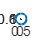

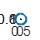

function main
    tspan = 0:0.001:2000;
    p_values = 0.:0.001:0.5;
    C_S_final = zeros(size(p_values));
    C_sigma_final = zeros(size(p_values));
    diss_final = zeros(size(p_values));
    k = 50; alpha = 0.1; q = 3;
    for i = 1:length(p_values)
        p = p_values(i);
        y0 = zeros(10,1);
        y0(1) = 1;
        [t, y] = ode45(@(t,y) ode_system(t, y, k, p, alpha, q), tspan, y0);

        c_uu = y(:,1) + y(:,2) + y(:,3) + y(:,4);
        c_ud = y(:,2) + y(:,5) + y(:,6) + y(:,7);
        c_du = y(:,3) + y(:,6) + y(:,8) + y(:,9);
        c_dd = y(:,4) + y(:,7) + y(:,9) + y(:,10);
        c_S = c_uu + c_ud;
        c_sigma = c_uu + c_du;
        diss = c_ud + c_du;
        C_S_final(i) = c_S(end);
        C_sigma_final(i) = c_sigma(end);
        diss_final(i) = diss(end);
    end

    figure;
    plot(p_values, C_S_final, '-o', 'LineWidth', 0.5);
    xlabel('p');
    ylabel('C_S');
    grid on;
    figure;
    plot(p_values, C_sigma_final, '-o', 'LineWidth', 0.5);
    xlabel('p');
    ylabel('C_{sigma}');
    grid on

    res = [p_values; C_S_final; C_sigma_final; diss_final]';
    
    scriptPath = fileparts(mfilename('fullpath'));
    fileName = fullfile(scriptPath, "genEPO_with_self_anticonformity_phase_diagram_q"+string(q)+"_alpha"+sprintf('%0.2f',alpha)+"_k_"+sprintf('%0.0f', k)+".txt");
    fileID = fopen(fileName,'a+');
    fprintf(fileID,'\n ');
    fclose(fileID);
    writematrix(res, fileName,'Delimiter','tab','WriteMode','append')
end


function dydt = ode_system(~, y, k, p, alpha, q)
    e_uu_uu = y(1); e_uu_ud = y(2); e_uu_du = y(3); e_uu_dd = y(4);
    e_ud_ud = y(5); e_ud_du = y(6); e_ud_dd = y(7);
    e_du_du = y(8); e_du_dd = y(9); 
    e_dd_dd = y(10);

    c_uu = e_uu_uu + e_uu_ud + e_uu_du + e_uu_dd;
    c_ud = e_uu_ud + e_ud_ud + e_ud_du + e_ud_dd;
    c_du = e_uu_du + e_ud_du + e_du_du + e_du_dd;
    c_dd = e_uu_dd + e_ud_dd + e_du_dd + e_dd_dd;

    theta_uu_uu = safe_divide(e_uu_uu, c_uu);
    theta_uu_ud = safe_divide(e_uu_ud, c_uu);
    theta_uu_du = safe_divide(e_uu_du, c_uu);
    theta_uu_dd = safe_divide(e_uu_dd, c_uu);
    
    theta_ud_uu = safe_divide(e_uu_ud, c_ud);
    theta_ud_ud = safe_divide(e_ud_ud, c_ud);
    theta_ud_du = safe_divide(e_ud_du, c_ud);
    theta_ud_dd = safe_divide(e_ud_dd, c_ud);
    
    theta_du_uu = safe_divide(e_uu_du, c_du);
    theta_du_ud = safe_divide(e_ud_du, c_du);
    theta_du_du = safe_divide(e_du_du, c_du);
    theta_du_dd = safe_divide(e_du_dd, c_du);
    
    theta_dd_uu = safe_divide(e_uu_dd, c_dd);
    theta_dd_ud = safe_divide(e_ud_dd, c_dd);
    theta_dd_du = safe_divide(e_du_dd, c_dd);
    theta_dd_dd = safe_divide(e_dd_dd, c_dd);
    


    dydt = zeros(10,1);
    dydt(1) = fun_e_uu_uu(k, p, alpha, q, c_uu, c_ud, c_du, c_dd, ...
                           theta_uu_uu, theta_uu_ud, theta_uu_du, theta_uu_dd, ...
                           theta_ud_uu, theta_ud_ud, theta_ud_du, theta_ud_dd, ...
                           theta_du_uu, theta_du_ud, theta_du_du, theta_du_dd, ...
                           theta_dd_uu, theta_dd_ud, theta_dd_du, theta_dd_dd);
    
    dydt(2) = fun_e_uu_ud(k, p, alpha, q, c_uu, c_ud, c_du, c_dd, ...
                           theta_uu_uu, theta_uu_ud, theta_uu_du, theta_uu_dd, ...
                           theta_ud_uu, theta_ud_ud, theta_ud_du, theta_ud_dd, ...
                           theta_du_uu, theta_du_ud, theta_du_du, theta_du_dd, ...
                           theta_dd_uu, theta_dd_ud, theta_dd_du, theta_dd_dd);
    dydt(3) = fun_e_uu_du(k, p, alpha, q, c_uu, c_ud, c_du, c_dd, ...
                           theta_uu_uu, theta_uu_ud, theta_uu_du, theta_uu_dd, ...
                           theta_ud_uu, theta_ud_ud, theta_ud_du, theta_ud_dd, ...
                           theta_du_uu, theta_du_ud, theta_du_du, theta_du_dd, ...
                           theta_dd_uu, theta_dd_ud, theta_dd_du, theta_dd_dd);
    dydt(4) = fun_e_uu_dd(k, p, alpha, q, c_uu, c_ud, c_du, c_dd, ...
                           theta_uu_uu, theta_uu_ud, theta_uu_du, theta_uu_dd, ...
                           theta_ud_uu, theta_ud_ud, theta_ud_du, theta_ud_dd, ...
                           theta_du_uu, theta_du_ud, theta_du_du, theta_du_dd, ...
                           theta_dd_uu, theta_dd_ud, theta_dd_du, theta_dd_dd);
    dydt(5) = fun_e_ud_ud(k, p, alpha, q, c_uu, c_ud, c_du, c_dd, ...
                           theta_uu_uu, theta_uu_ud, theta_uu_du, theta_uu_dd, ...
                           theta_ud_uu, theta_ud_ud, theta_ud_du, theta_ud_dd, ...
                           theta_du_uu, theta_du_ud, theta_du_du, theta_du_dd, ...
                           theta_dd_uu, theta_dd_ud, theta_dd_du, theta_dd_dd);
    dydt(6) = fun_e_ud_du(k, p, alpha, q, c_uu, c_ud, c_du, c_dd, ...
                           theta_uu_uu, theta_uu_ud, theta_uu_du, theta_uu_dd, ...
                           theta_ud_uu, theta_ud_ud, theta_ud_du, theta_ud_dd, ...
                           theta_du_uu, theta_du_ud, theta_du_du, theta_du_dd, ...
                           theta_dd_uu, theta_dd_ud, theta_dd_du, theta_dd_dd);
    dydt(7) = fun_e_dd_ud(k, p, alpha, q, c_uu, c_ud, c_du, c_dd, ...
                           theta_uu_uu, theta_uu_ud, theta_uu_du, theta_uu_dd, ...
                           theta_ud_uu, theta_ud_ud, theta_ud_du, theta_ud_dd, ...
                           theta_du_uu, theta_du_ud, theta_du_du, theta_du_dd, ...
                           theta_dd_uu, theta_dd_ud, theta_dd_du, theta_dd_dd);
    dydt(8) = fun_e_du_du(k, p, alpha, q, c_uu, c_ud, c_du, c_dd, ...
                           theta_uu_uu, theta_uu_ud, theta_uu_du, theta_uu_dd, ...
                           theta_ud_uu, theta_ud_ud, theta_ud_du, theta_ud_dd, ...
                           theta_du_uu, theta_du_ud, theta_du_du, theta_du_dd, ...
                           theta_dd_uu, theta_dd_ud, theta_dd_du, theta_dd_dd);
    dydt(9) = fun_e_dd_du(k, p, alpha, q, c_uu, c_ud, c_du, c_dd, ...
                           theta_uu_uu, theta_uu_ud, theta_uu_du, theta_uu_dd, ...
                           theta_ud_uu, theta_ud_ud, theta_ud_du, theta_ud_dd, ...
                           theta_du_uu, theta_du_ud, theta_du_du, theta_du_dd, ...
                           theta_dd_uu, theta_dd_ud, theta_dd_du, theta_dd_dd);
    dydt(10) = fun_e_dd_dd(k, p, alpha, q, c_uu, c_ud, c_du, c_dd, ...
                           theta_uu_uu, theta_uu_ud, theta_uu_du, theta_uu_dd, ...
                           theta_ud_uu, theta_ud_ud, theta_ud_du, theta_ud_dd, ...
                           theta_du_uu, theta_du_ud, theta_du_du, theta_du_dd, ...
                           theta_dd_uu, theta_dd_ud, theta_dd_du, theta_dd_dd);
end

function val = safe_divide(num, denom)
    if denom ~= 0
        val = num / denom;
    else
        val = 0;
    end
end

main;